# Correlation

A numerical measure of the degree to which two variables vary together *according to some specified pattern*.

There are multiple kinds of correlation: Pearson, Spearman, Distance etc. They are used according to the nature of the data being analyzed.

Here, we will focus on Pearson correlation.

## Pearson correlation

Pearson correlation measures how strongly two variables are related linearly.


$$r = \frac{\sum_{i=1}^{n}(x_i-\bar{x})(y_i-\bar{y})}{\sqrt{\sum_{i=1}^{n}(x_i-\bar{x})^2}\sqrt{\sum_{i=1}^{n}(y_i-\bar{y})^2}} = \frac{\text{Cov}(X,Y)}{\sigma_X \sigma_Y}$$


In MATLAB, we have the `corrcoef` function for calculating this.

### Let's set up our data!

rng(7)
n = 60;
x = randn(n,1)

x =    -0.8968
    0.6858
   -0.3878
    0.6531
    1.1512
    0.0867
    0.0016
   -1.1992
   -0.1891
   -0.0004
    0.8534
    0.7568
   -0.3225
   -1.6165
   -0.7890


### The other variable

y = 0.8*x + 0.5*randn(n,1)

y =    -0.1948
    0.1460
   -0.6571
    0.6742
    0.2903
    0.4754
    0.6457
   -0.3217
   -0.2022
    0.7756
    0.0937
    0.5004
   -0.2857
   -0.7718
   -0.6506


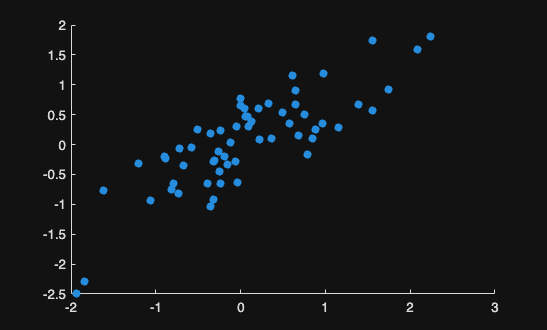

scatter(x,y,'filled')

We can already see that there is some linear relationship between these two variables.

### The Pearson's $r$

R = corrcoef(x,y)

R =     1.0000    0.8217
    0.8217    1.0000


So, our correlation coefficient would be the element at the 1st row and 2nd column (or 2nd row and 1st column).

We have *positive correlation*: both increase/decrease together.

### What about a different variable $y$

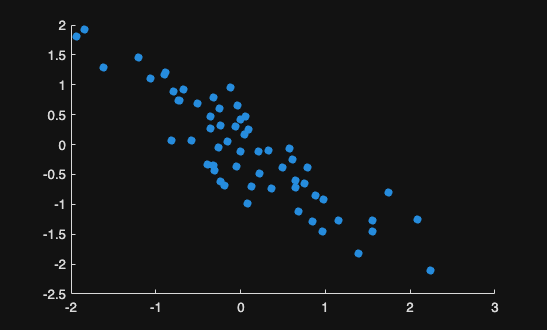

y = -0.8*x + 0.5*randn(n,1);
scatter(x,y,'filled')

R = corrcoef(x,y)

R =     1.0000   -0.8808
   -0.8808    1.0000


We have *negative correlation* here: when one variable increases, the other decreases!

### Let's try a different pair of variables

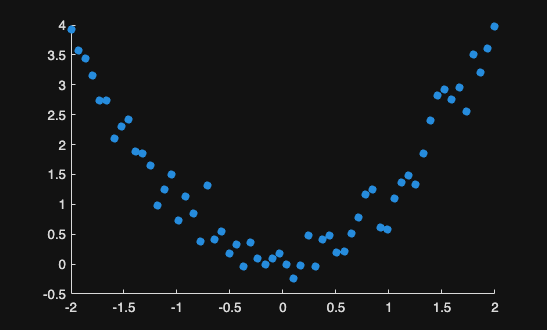

x2 = linspace(-2,2,n)';
y2 = x2.^2 + 0.25*randn(n,1);
scatter(x2, y2, "filled")

R = corrcoef(x2,y2)

R =     1.0000    0.0413
    0.0413    1.0000


The Pearson's coefficient is 0 in this case: we have *non-linear relation*.